# ROC

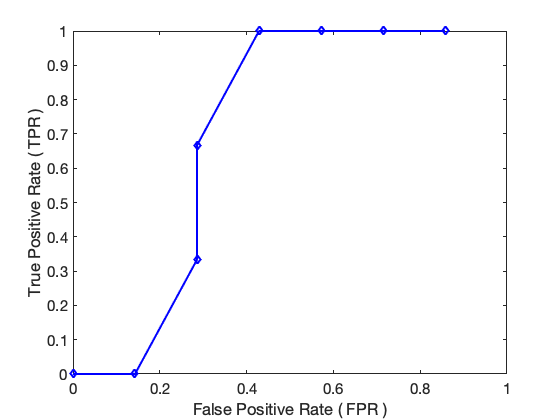

clearvars; close all; clc;

rng(1)


N = 1000; %number of sampled points to use


% Creat the randome variables
x = randn(N,1);
y = randn(N,1);
z = randn(N,1);

f = 2*x -3*y +0.9*z.^2;

% Add wighte gaussian noise to the function
f = f + 50*randn(size(f));

% create the library of candidate functions
Phi = [ones(size(x)), x, y, z, ... %linear terms
     x.^2, x.*y, x.*z, y.^2, y.*z, z.^2]; % quadratic terms

d = size(Phi,2);% Regression dimension, or, number of candidate functions

% According to the order of A, the optimal solution should be
TS = [0, 2, -3, 0, 0, 0, 0, 0, 0, 0.9]';



B = lasso(Phi,f);

for i=1:size(B,2)
    FP(i) = sum( ~TS .* ~~B(:,i));
    TP(i) = sum(~~TS .* ~~B(:,i));
end

FPR = FP./sum(~TS);
TPR = TP./sum(~~TS);

plot(FPR,TPR,'-db','LineWidth',2)
axis([0 1 0 1])
ylabel('True Positive Rate ( TPR )')
xlabel('False Positive Rate ( FPR )')
set(gca,'FontSize',15)